# Newton-Raphson Method

close all, clear all, clc
set_defaults()

To  find the *root* of the non-linear algebraic system of `N` equations `r``(``u``) = ``0`. To do so we linearize the the system of equation by expanding it in a Taylor series and find the root of the linearized system to obtain an updated solution. Given an iterate, $\mathbf{u}^k$, we linearize the solution around it 

$\mathbf{r}(\mathbf{u}^{k+1}) \approx \mathbf{r}(\mathbf{u}^k) + \delta\mathbf{u}^k\,\left. \frac{\mathrm{d}\mathbf{r}(\mathbf{u})}{\mathrm{d}\mathbf{u}}\right|_{\mathbf{u}^k}=0$,

so that the root of the linearized problem, $\mathbf{u}^{k+1} = \mathbf{u}^k + \delta\mathbf{u}^k$, is the updated iterate. Here the derivative of the residual is generally known as the Jacobian matrix 


$$\mathbf{J}(\mathbf{u})\equiv\frac{\mathrm{d}\mathbf{r}(\mathbf{u})}{\mathrm{d}\mathbf{u}}$$


which is an `N` by `N` matrix of the `N` residuals in each cell with respect to the N unknowns in each cell. In general, computing `J` is the main challenge in implementing the Newton-Raphson method - in practice. 

Given the residual and the Jacobian for an iterate, u, we can solve the following linear system for the update

`J``(``u``)*``du`` = -``r``(``u``)`

and compute the new iterate as

`u`` = ``u`` + ``du``.`

The iteration is initialized with `u`` = ``uold` and terminated when both $|\mathbf{r}(\mathbf{u})| < \varepsilon$ and $|\mathbf{du}| < \varepsilon$ or the number of iterations exceeds a maximum. The latter is important, because the iteration is not guaranteed to converge! If the the initial guess is in the *basin of convergence* of the Newton-Raphson method, then it converges quardatically. Therefore the initial guess is critical to the convergence of the Newton-Raphson method.

## Simple scalar example

Find the zero of the following non-linear function


$$r(x) = e^x-2$$


r = @(x) exp(x)-2;
xplot = linspace(0,1.5,100);
plot(xplot,r(xplot),[0 1.5],[0 0],':'), hold on
plot(log(2),0,'o','markerfacecolor','w')

To solve this with the Newton-Raphson method, we need the Jacobian, $J = \mbox{d}r/\mbox{d}x = \exp(x)$, an intial guess, $x_0 = 1$, a convergence tolerance $\varepsilon = 10^{-6}$ and a maximum number of iterations Niter = 6;.

x0 = 2.5;
tol = 1e-6;
Niter = 6;
J = @(x) exp(x);
i = 1; x = x0; dx = 1; 
fprintf('Newton-Raphson iterations:\n')

Newton-Raphson iterations:


while (norm(r(x)) > tol || dx > tol) && i <= Niter
    dx = -r(x)/J(x);
    x = x + dx;
    i = i + 1;
    fprintf('it = %d: r = %3.2e  dx = %3.2e\n',i,r(x),dx)
end

it = 2: r = 3.28e+00  dx = -8.36e-01
it = 3: r = 8.37e-01  dx = -6.21e-01
it = 4: r = 1.12e-01  dx = -2.95e-01
it = 5: r = 2.93e-03  dx = -5.31e-02
it = 6: r = 2.14e-06  dx = -1.46e-03
it = 7: r = 1.15e-12  dx = -1.07e-06


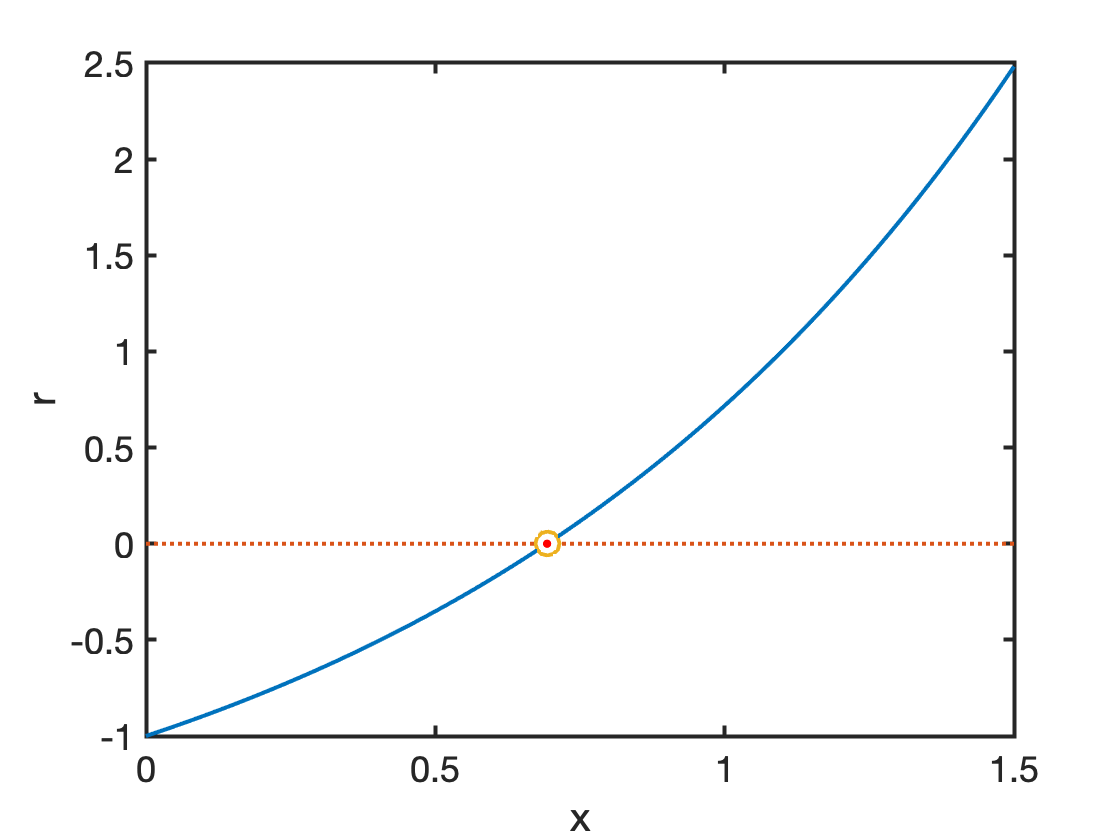

plot(x,0,'r.')
xlabel 'x', ylabel 'r'

For a simple function like this with a single root, the Newton-Raphson method converges without problem. Note that the residual and update decrease by two orders of magnitude in the final few iterations, an indication that the convergence is quadratic.

**Go show the script demo_scalar_newton.m**

## **Simple 5 by 5 system example**

Consider the 5 non-linear algebraic equations.


$$r_1(\mathbf{u}) = 3u_1-2\sqrt{u_3u_4}\\
r_2(\mathbf{u})=\frac{u_2^2}{2}+u_5e^{u_3}+5u_2\\
r_3(\mathbf{u})=7u_1^2u_3+\pi u_4+2u_5^{\frac{1}{3}}\\
r_4(\mathbf{u}) = -\sqrt{u_2}+3(u_1-u_5)^2+u_3u_4\\
r_5(\mathbf{u}) = u_1-4u_2+4u_5$$


We can create a system non-linear algebraic equations, $\mathbf{r}'$, with solution $\mathbf{u}^*=[1,\, 2,\, 3,\, 2,\, 1]^T$ by defining

$\mathbf{r}' (\mathbf{u})= \mathbf{r}(\mathbf{u}) - \mathbf{r}(\mathbf{u}^*)$.

Note that $\mathbf{u}^*$ is only one solution, there may be more!

% analytic solution
u_star = [1;2;3;2;1];

% residual function
r = @(u) [3*u(1)-2*sqrt(u(3).*u(4));...
          .5*u(2).^2+u(5).*exp(u(3))+5*u(2);...
          7*u(1).^2.*u(3)+pi*u(4)+2*u(5).^(1/3);...
          -sqrt(u(2))+3*(u(1)-u(5)).^2+u(3).*u(4);...
          u(1)-4*u(2)+4*u(5)];
r_prime = @(u) r(u)-r(u_star); % generates a residual with u_star as solution

The Jacobian is now a 5 by 5 matrix given by.


$$\mathbf{J} = \left[\matrix{ 3 & 0 &\frac{-u_4}{\sqrt{u_3u_4}} & \frac{-u_3}{\sqrt{u_3u_4}} & 0 \cr 0 & u_2+5 & u_5 e^{u_3}& 0 & e^{u_3}\cr 14 u_1u_3& 0&7u_1^2&\pi&\frac{2}{3}u_5^{-\frac{2}{3}} \cr 6(u_1-u_5) &-\frac{1}{2\sqrt{u_2}}&u_4&u_3&-6(u_1-u_5) \cr 1 & -4 & 0 & 0 &4 }\right]$$


J = @(u) [3,0,-u(4)./sqrt(u(3).*u(4)),-u(3)./sqrt(u(3).*u(4)),0;...
          0,u(2)+5,u(5).*exp(u(3)),0,exp(u(3));...
          14*u(1).*u(3),0,7*u(1).^2,pi,2/3*u(5).^(-2/3);...
          6*(u(1)-u(5)),-1/2/sqrt(u(2)),u(4),u(3),-6*(u(1)-u(5));...
          1,-4,0,0,4];
      

This can now be solved for different initial guesses

u = 2*[1;1;1;1;1]; % initial guess - converges
% u = [1;1;1;1;1]; % does not converge
Jac = J(u)

Jac =     3.0000         0   -1.0000   -1.0000         0
         0    7.0000   14.7781         0    7.3891
   56.0000         0   28.0000    3.1416    0.4200
         0   -0.3536    2.0000    2.0000         0
    1.0000   -4.0000         0         0    4.0000


Here `J` is essentially a *full* matrix.

tol = 1e-8; 
imax = 20;

fprintf('\nSolving 5x5 system with Newton-Raphson:');


Solving 5x5 system with Newton-Raphson:

i = 1; nres = 1; ndu = 1; % initialize Newton
while (nres > tol || ndu > tol) && i <= imax
    du = - J(u)\r(u); ndu = norm(du);
    u = u+du; nres = norm(r(u));
    fprintf('%d: res = %3.2e, du = %3.2e;\n',i,nres,ndu)
    if (nres < tol && ndu < tol) && i < imax
        fprintf('\nNewton iteration converged to tol = %3.2e\n',tol)
    elseif (nres > tol || ndu > tol) && i >= imax
        fprintf('\nNewton iteration did NOT converge to tol = %3.2e in %d iterations!\n',tol,i)
    end 
    i = i+1;
end

1: res = 1.35e+00, du = 1.44e+00;
2: res = 1.60e-01, du = 5.53e-01;
3: res = 3.60e-02, du = 1.43e-01;
4: res = 2.74e-03, du = 4.48e-02;
5: res = 1.76e-05, du = 3.48e-03;
6: res = 6.78e-10, du = 2.16e-05;
7: res = 1.33e-15, du = 8.35e-10;



Newton iteration converged to tol = 1.00e-08


u

u =     1.0000
    2.0000
    3.0000
    2.0000
    1.0000


# Auxillary functions

## set_defaults()

function [] = set_defaults()
set(0, ...
    'defaultaxesfontsize',   18, ...
    'defaultaxeslinewidth',   2.0, ...
    'defaultlinelinewidth',   2.0, ...
    'defaultpatchlinewidth',  2.0,...
    'DefaultLineMarkerSize', 12.0);
end